addpath('./data');

Load the Dataset

load('trunk12-patches.mat');

% Extract training and testing data and labels
trainData = trunk.train.data;
trainLabels = trunk.train.labels;
testData = trunk.test.data;
testLabels = trunk.test.labels;

% Normalize the images to the range [0, 1]
trainData = double(trainData) / 255;
testData = double(testData) / 255;

Basic CNN Architecture

layers = [
    imageInputLayer([40 40 3]) 

    convolution2dLayer(3, 8, 'Padding', 'same') 

    maxPooling2dLayer(2, 'Stride', 2) 

    convolution2dLayer(3, 16, 'Padding', 'same')

    maxPooling2dLayer(2, 'Stride', 2) 

    fullyConnectedLayer(64) 

    fullyConnectedLayer(12)
    softmaxLayer 
    classificationLayer
];

Specify Training Options

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',30, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{testData, testLabels}, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');

Model Training

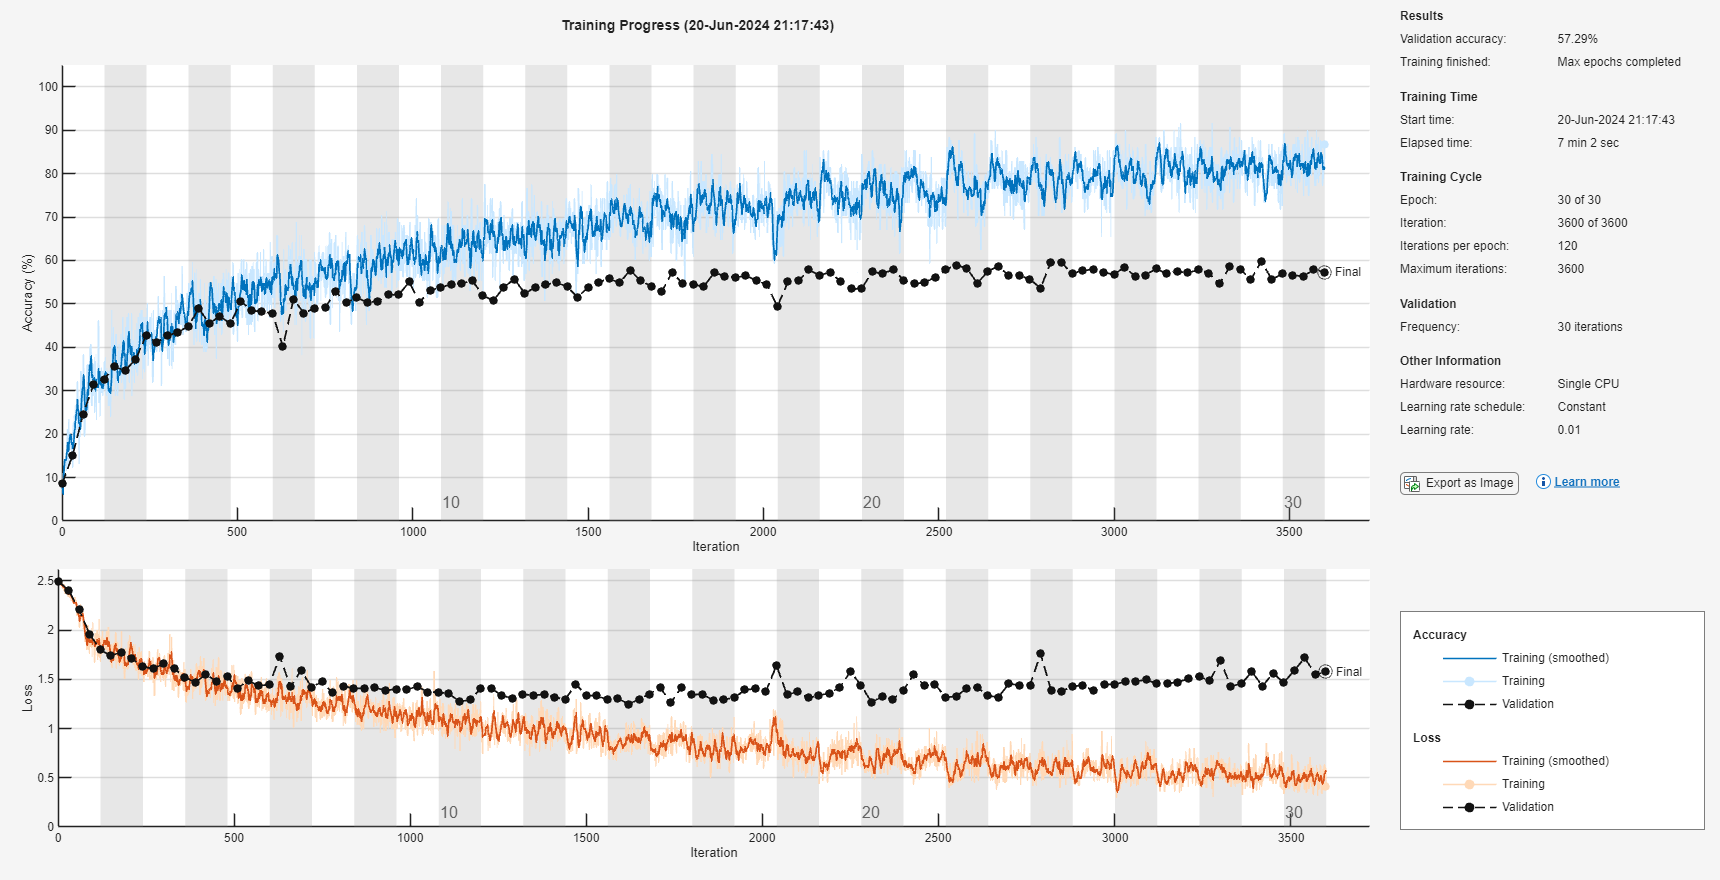

net = trainNetwork(trainData, trainLabels, layers, options);

Evaluate the Model

predictedLabels = classify(net, testData);
accuracy = sum(predictedLabels == testLabels) / numel(testLabels);
fprintf('Test accuracy: %.2f%%\n', accuracy * 100);

Test accuracy: 57.29%


Generate confusion matrix

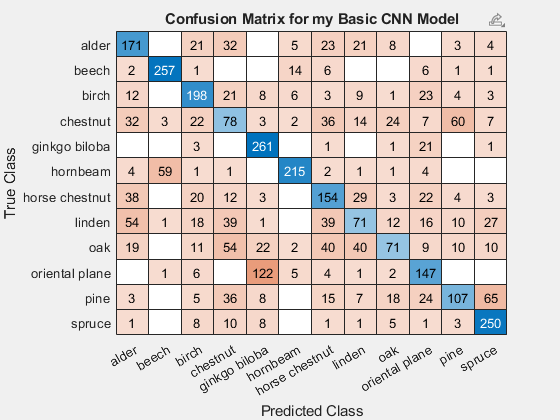

figure('Visible', 'on');
confusionchart(testLabels, predictedLabels);
title('Confusion Matrix for my Basic CNN Model');

drawnow;

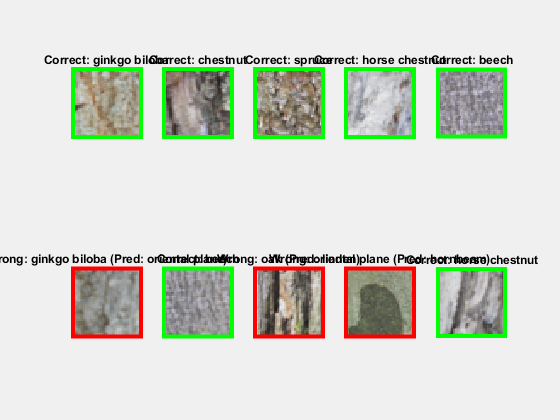

% Select a subset of test images for visualization
numSamples = 10; % Number of samples to visualize
sampleIndices = randperm(numel(testLabels), numSamples);

figure('Visible', 'on');
for i = 1:numSamples
    index = sampleIndices(i);
    img = testData(:,:,:,index);
    trueLabel = testLabels(index);
    predictedLabel = predictedLabels(index);
    
    subplot(2, numSamples/2, i);
    imshow(img, 'InitialMagnification', 'fit');
    
    if trueLabel == predictedLabel
        borderColor = 'g'; % Green for correct classification
        titleText = sprintf('Correct: %s', string(trueLabel));
    else
        borderColor = 'r'; % Red for incorrect classification
        titleText = sprintf('Wrong: %s (Pred: %s)', string(trueLabel), string(predictedLabel));
    end
    
    rectangle('Position', [0.5, 0.5, size(img, 2), size(img, 1)], 'EdgeColor', borderColor, 'LineWidth', 3);
    title(titleText);
end

drawnow;

Improving by adding pre-processing (Normalisation)

% Normalize the images to mean 0 and variance 1
meanTrain = mean(trainData(:));
stdTrain = std(trainData(:));
trainData = (trainData - meanTrain) / stdTrain;
testData = (testData - meanTrain) / stdTrain; % Use the same mean and std as train data

% Visualization of the original and normalized images
numSamples = 5; % Number of samples to visualize
sampleIndices = randperm(size(trunk.train.data, 4), numSamples);
sampleData = trunk.train.data(:,:,:,sampleIndices);
normalizedSampleData = double(sampleData) / 255;
normalizedSampleData = (normalizedSampleData - meanTrain) / stdTrain;

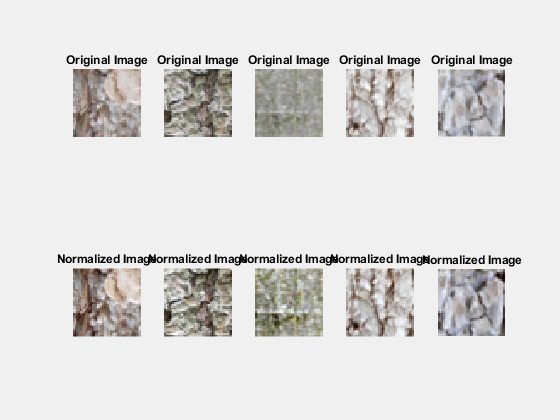


figure('Visible', 'on');

for i = 1:numSamples
    % Original image
    subplot(2, numSamples, i);
    imshow(uint8(sampleData(:,:,:,i)));
    title('Original Image');
    
    % Normalized image
    subplot(2, numSamples, numSamples + i);
    imshow(mat2gray(normalizedSampleData(:,:,:,i))); % mat2gray scales the image to [0, 1] for display
    title('Normalized Image');
end


layers = [
    imageInputLayer([40 40 3]) 

    convolution2dLayer(3, 8, 'Padding', 'same') 

    maxPooling2dLayer(2, 'Stride', 2)

    convolution2dLayer(3, 16, 'Padding', 'same') 

    maxPooling2dLayer(2, 'Stride', 2) 

    fullyConnectedLayer(64) 

    fullyConnectedLayer(12) 
    softmaxLayer 
    classificationLayer
];

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',30, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{testData, testLabels}, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');

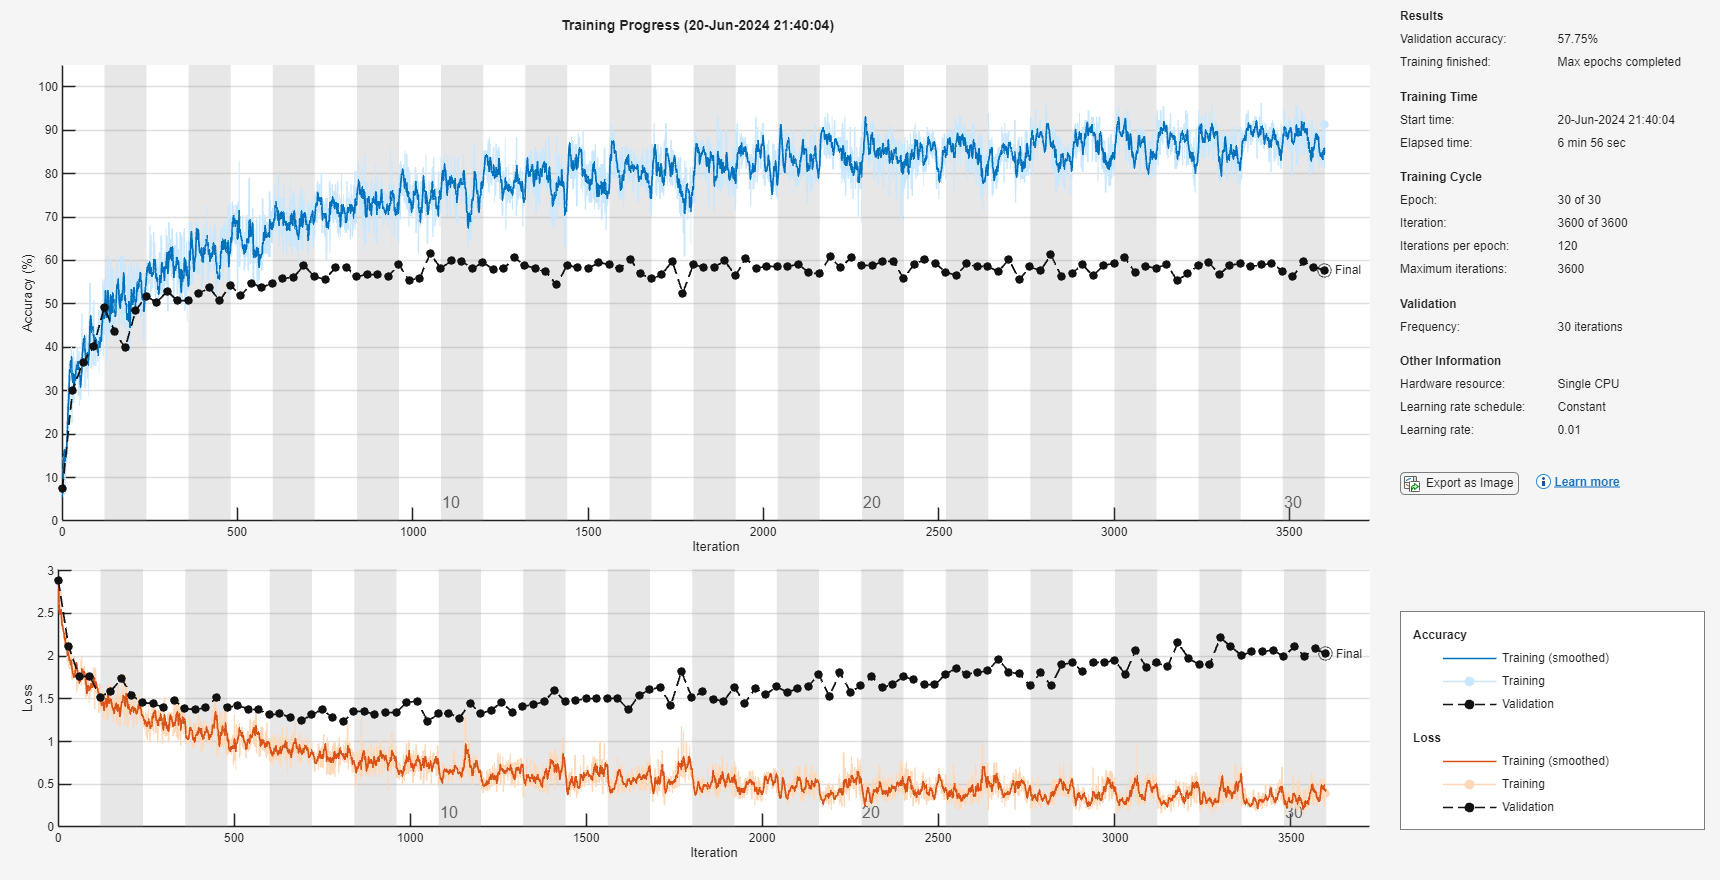

netImproved = trainNetwork(trainData, trainLabels, layers, options);

predictedLabels = classify(netImproved, testData);
accuracy = sum(predictedLabels == testLabels) / numel(testLabels);
fprintf('Test accuracy: %.2f%%\n', accuracy * 100);

Test accuracy: 57.75%


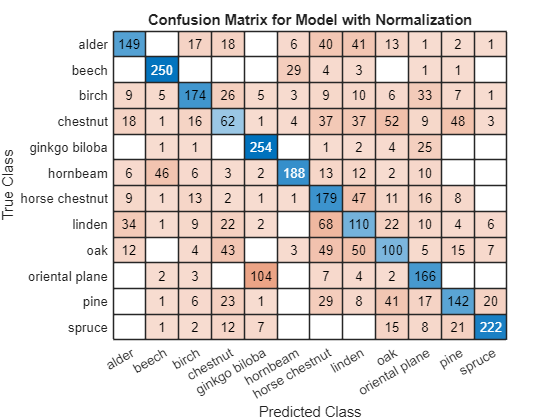

figure;
confusionchart(testLabels, predictedLabels);
title('Confusion Matrix for Model with Normalization');

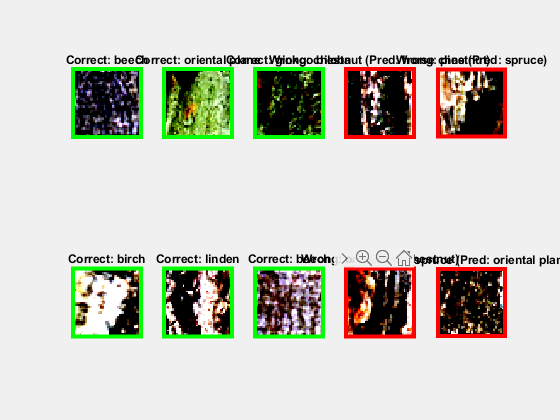

numSamples = 10;
sampleIndices = randperm(numel(testLabels), numSamples);

figure('Visible', 'on');
for i = 1:numSamples
    index = sampleIndices(i);
    img = testData(:,:,:,index);
    trueLabel = testLabels(index);
    predictedLabel = predictedLabels(index);
    
    subplot(2, numSamples/2, i);
    imshow(img, 'InitialMagnification', 'fit');
    
    if trueLabel == predictedLabel
        borderColor = 'g';
        titleText = sprintf('Correct: %s', string(trueLabel));
    else
        borderColor = 'r';
        titleText = sprintf('Wrong: %s (Pred: %s)', string(trueLabel), string(predictedLabel));
    end
    
    rectangle('Position', [0.5, 0.5, size(img, 2), size(img, 1)], 'EdgeColor', borderColor, 'LineWidth', 3);
    title(titleText);
end

drawnow;


Not Normalised Data with Enhanced CNN model

trainData_not_normalised = trunk.train.data;
trainLabels = trunk.train.labels;
testData_not_normalised = trunk.test.data;
testLabels = trunk.test.labels;

layers = [
    imageInputLayer([40 40 3], 'Normalization', 'none')
    
    convolution2dLayer(3, 32, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(3, 64, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(3, 128, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    
    fullyConnectedLayer(256)
    dropoutLayer(0.5) % Add dropout to prevent overfitting
    reluLayer
    
    fullyConnectedLayer(numel(unique(trainLabels)))
    softmaxLayer
    classificationLayer
];

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',20, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{testData_not_normalised, testLabels}, ...
    'ValidationFrequency',15, ...
    'Verbose',false, ...
    'Plots','training-progress');

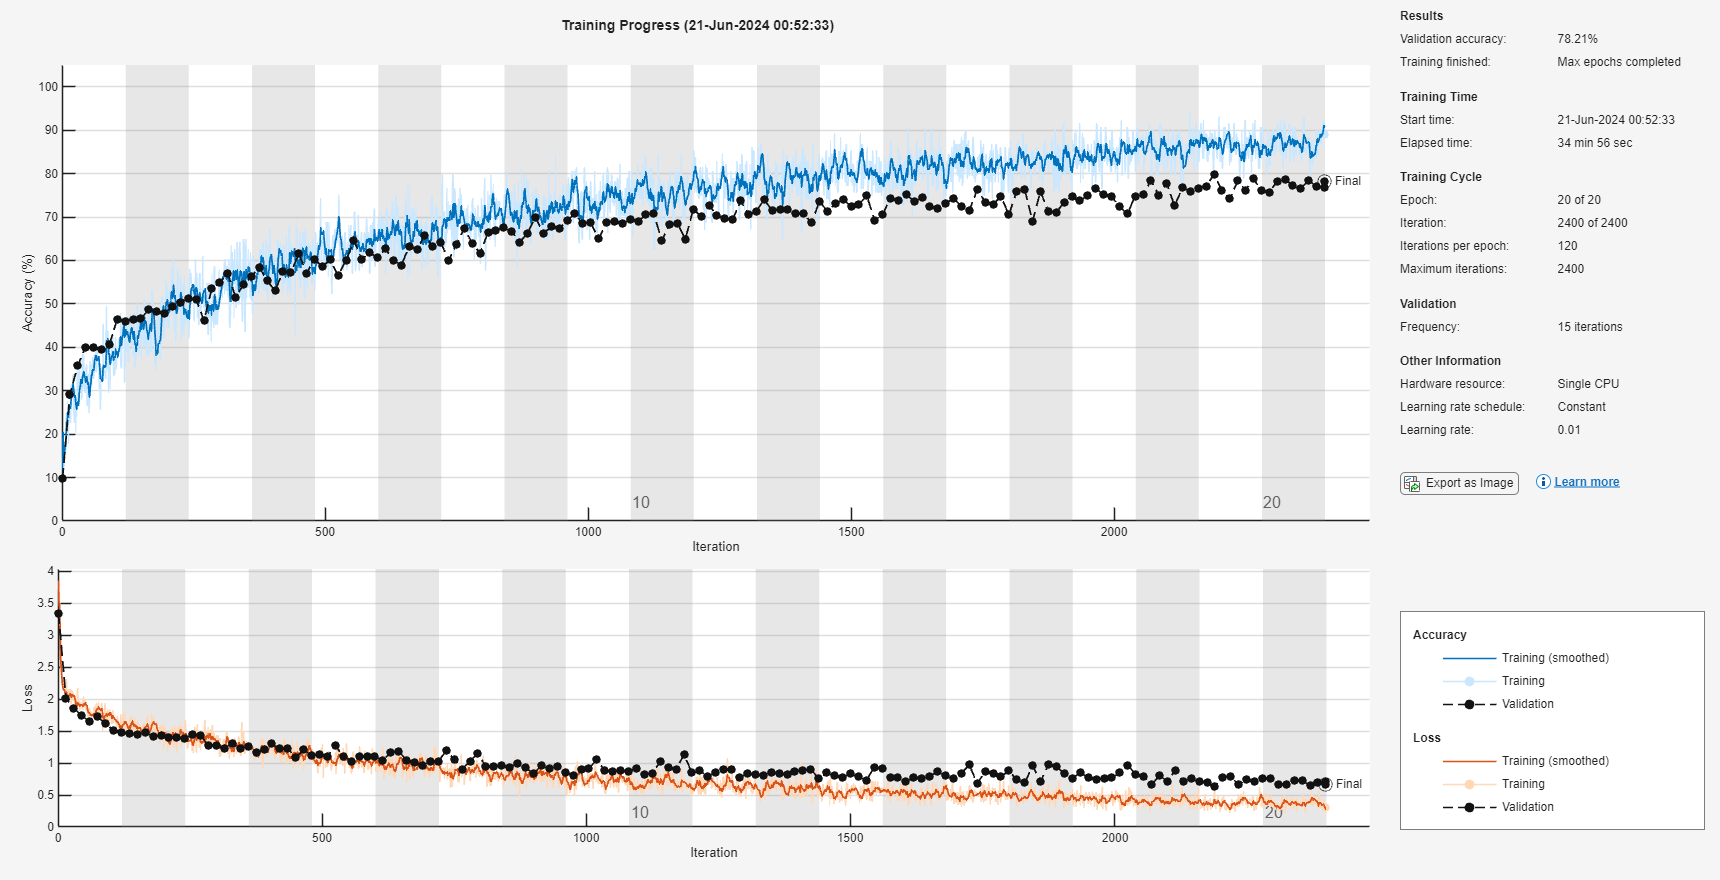

% Train the network
netImproved2 = trainNetwork(trainData_not_normalised, trainLabels, layers, options);

predictedLabels = classify(netImproved2, testData_not_normalised);
accuracy = sum(predictedLabels == testLabels) / numel(testLabels);
fprintf('Test accuracy: %.2f%%\n', accuracy * 100);

Test accuracy: 78.21%


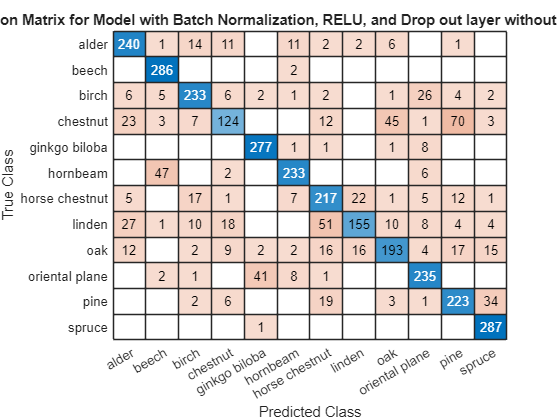

figure;
confusionchart(testLabels, predictedLabels);
title('Confusion Matrix for Model with Batch Normalization, RELU, and Drop out layer without normalised Data');

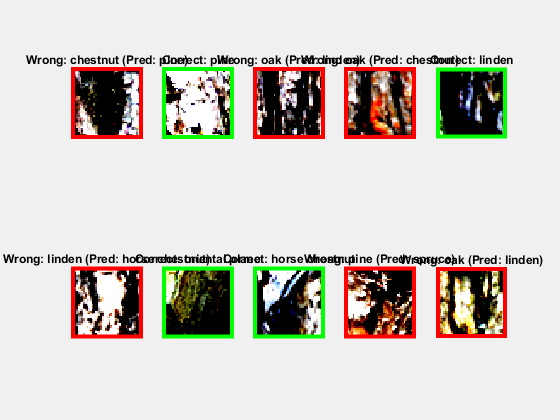

numSamples = 10;
sampleIndices = randperm(numel(testLabels), numSamples);

figure('Visible', 'on');
for i = 1:numSamples
    index = sampleIndices(i);
    img = testData(:,:,:,index);
    trueLabel = testLabels(index);
    predictedLabel = predictedLabels(index);
    
    subplot(2, numSamples/2, i);
    imshow(img, 'InitialMagnification', 'fit');
    
    if trueLabel == predictedLabel
        borderColor = 'g'; % Green for correct classification
        titleText = sprintf('Correct: %s', string(trueLabel));
    else
        borderColor = 'r'; % Red for incorrect classification
        titleText = sprintf('Wrong: %s (Pred: %s)', string(trueLabel), string(predictedLabel));
    end
    
    rectangle('Position', [0.5, 0.5, size(img, 2), size(img, 1)], 'EdgeColor', borderColor, 'LineWidth', 3);
    title(titleText);
end


drawnow;

Normalised Data with Enhanced CNN model

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',20, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{testData, testLabels}, ...
    'ValidationFrequency',15, ...
    'Verbose',false, ...
    'Plots','training-progress');

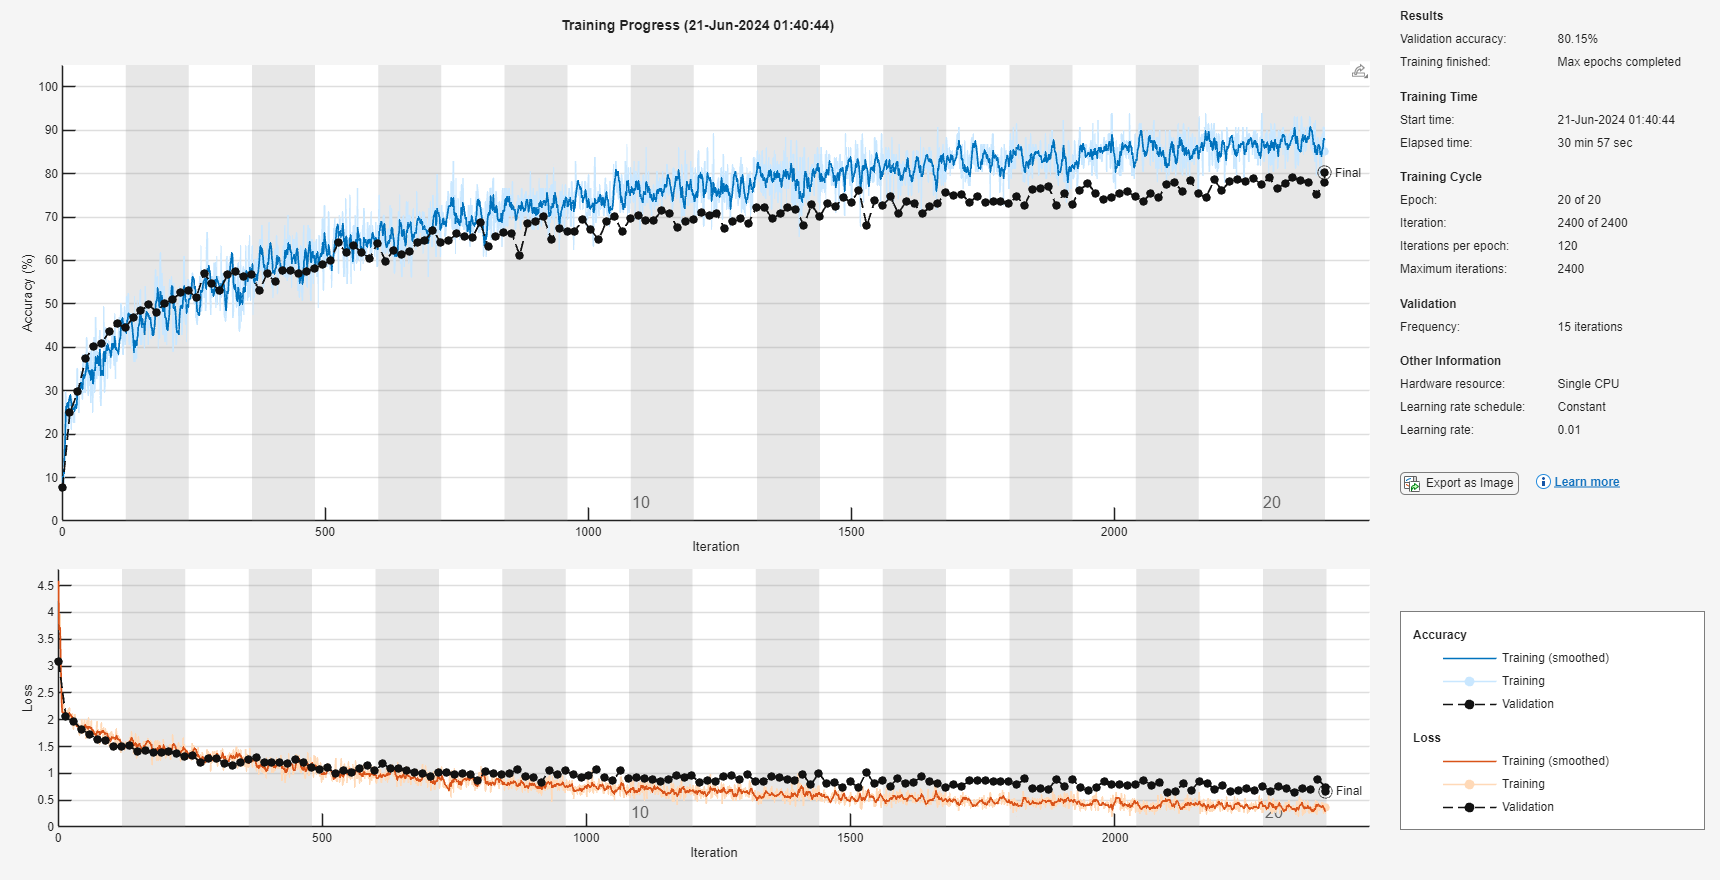

% Train the network
netImproved3 = trainNetwork(trainData, trainLabels, layers, options);

predictedLabels = classify(netImproved3, testData);
accuracy = sum(predictedLabels == testLabels) / numel(testLabels);
fprintf('Test accuracy: %.2f%%\n', accuracy * 100);

Test accuracy: 80.15%


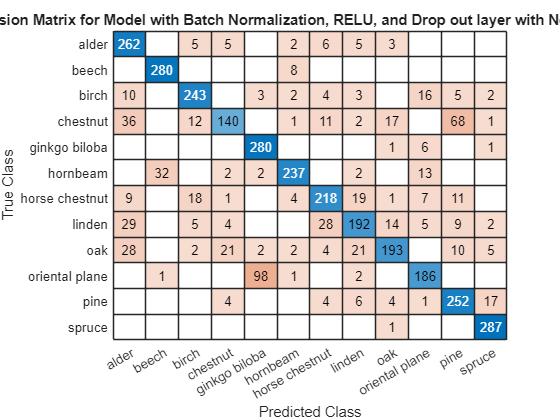

figure;
confusionchart(testLabels, predictedLabels);
title('Confusion Matrix for Model with Batch Normalization, RELU, and Drop out layer with Normalised Data');

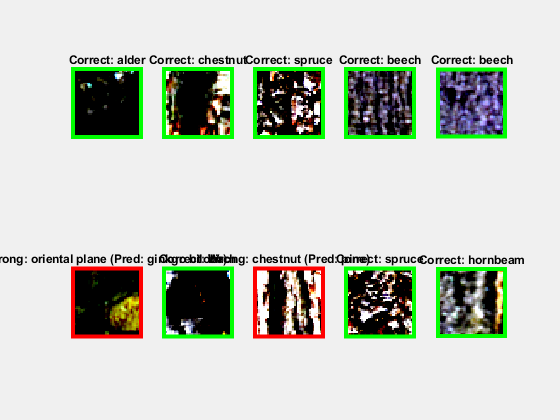

numSamples = 10;
sampleIndices = randperm(numel(testLabels), numSamples);

figure('Visible', 'on');
for i = 1:numSamples
    index = sampleIndices(i);
    img = testData(:,:,:,index);
    trueLabel = testLabels(index);
    predictedLabel = predictedLabels(index);
    
    subplot(2, numSamples/2, i);
    imshow(img, 'InitialMagnification', 'fit');
    
    if trueLabel == predictedLabel
        borderColor = 'g'; % Green for correct classification
        titleText = sprintf('Correct: %s', string(trueLabel));
    else
        borderColor = 'r'; % Red for incorrect classification
        titleText = sprintf('Wrong: %s (Pred: %s)', string(trueLabel), string(predictedLabel));
    end
    
    rectangle('Position', [0.5, 0.5, size(img, 2), size(img, 1)], 'EdgeColor', borderColor, 'LineWidth', 3);
    title(titleText);
end

drawnow;

Remove ReLU Activation from Enhanced Model with Normalised Data

layers = [
    imageInputLayer([40 40 3], 'Normalization', 'none')
    
    convolution2dLayer(3, 32, 'Padding', 'same')
    batchNormalizationLayer
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(3, 64, 'Padding', 'same')
    batchNormalizationLayer
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(3, 128, 'Padding', 'same')
    batchNormalizationLayer
    maxPooling2dLayer(2, 'Stride', 2)
    
    fullyConnectedLayer(256)
    dropoutLayer(0.5) % Add dropout to prevent overfitting
    
    fullyConnectedLayer(numel(unique(trainLabels)))
    softmaxLayer
    classificationLayer
];

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',20, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{testData, testLabels}, ...
    'ValidationFrequency',15, ...
    'Verbose',false, ...
    'Plots','training-progress');

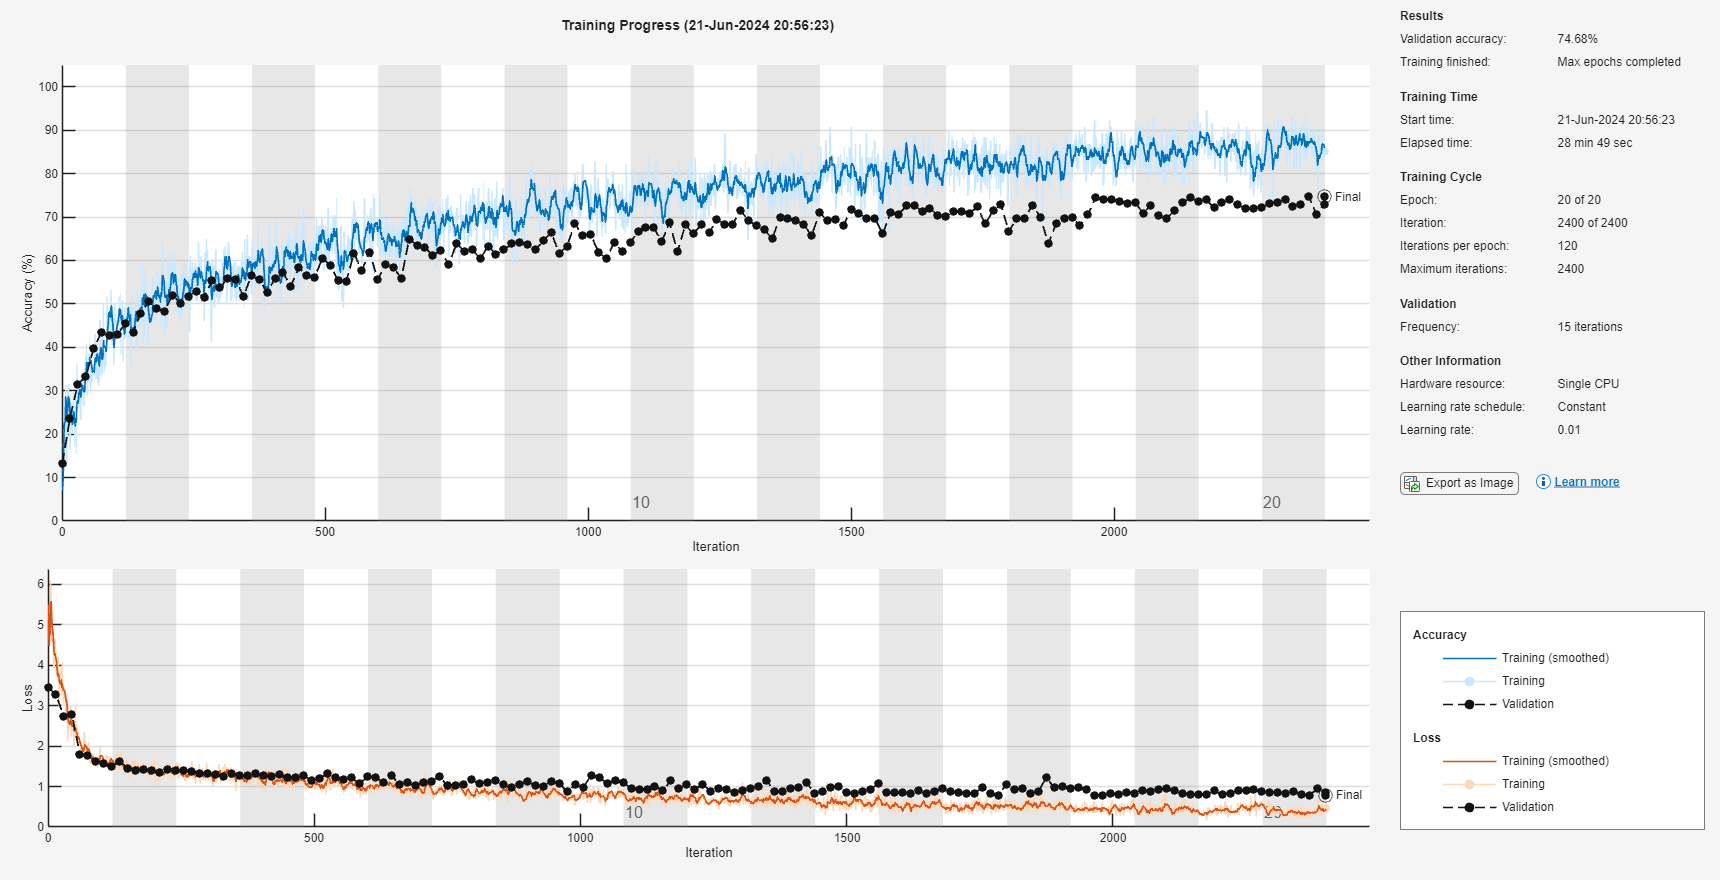

% Train the network
netImproved4 = trainNetwork(trainData, trainLabels, layers, options);

predictedLabels = classify(netImproved4, testData);
accuracy = sum(predictedLabels == testLabels) / numel(testLabels);
fprintf('Test accuracy: %.2f%%\n', accuracy * 100);

Test accuracy: 74.68%


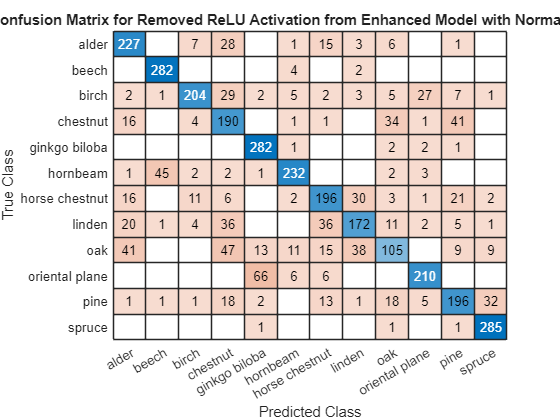

figure;
confusionchart(testLabels, predictedLabels);
title('Confusion Matrix for Removed ReLU Activation from Enhanced Model with Normalised Data');

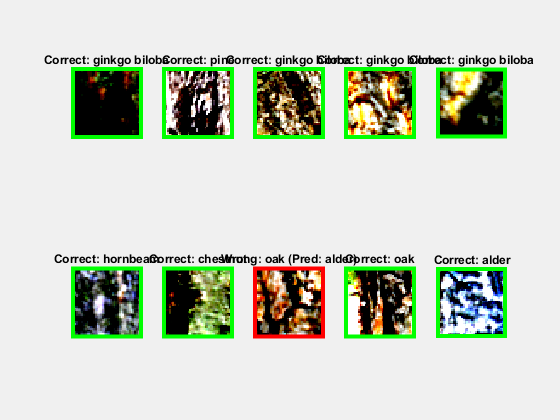

numSamples = 10; 
sampleIndices = randperm(numel(testLabels), numSamples);

figure('Visible', 'on');
for i = 1:numSamples
    index = sampleIndices(i);
    img = testData(:,:,:,index);
    trueLabel = testLabels(index);
    predictedLabel = predictedLabels(index);
    
    subplot(2, numSamples/2, i);
    imshow(img, 'InitialMagnification', 'fit');
    
    if trueLabel == predictedLabel
        borderColor = 'g'; 
        titleText = sprintf('Correct: %s', string(trueLabel));
    else
        borderColor = 'r'; 
        titleText = sprintf('Wrong: %s (Pred: %s)', string(trueLabel), string(predictedLabel));
    end
    
    rectangle('Position', [0.5, 0.5, size(img, 2), size(img, 1)], 'EdgeColor', borderColor, 'LineWidth', 3);
    title(titleText);
end

drawnow;

Removed dropout layer from Enhanced Model with Normalised Data

layers = [
    imageInputLayer([40 40 3], 'Normalization', 'none')
    
    convolution2dLayer(3, 32, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(3, 64, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(3, 128, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    
    fullyConnectedLayer(256)
    reluLayer
    
    fullyConnectedLayer(numel(unique(trainLabels)))
    softmaxLayer
    classificationLayer
];

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',20, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{testData, testLabels}, ...
    'ValidationFrequency',15, ...
    'Verbose',false, ...
    'Plots','training-progress');

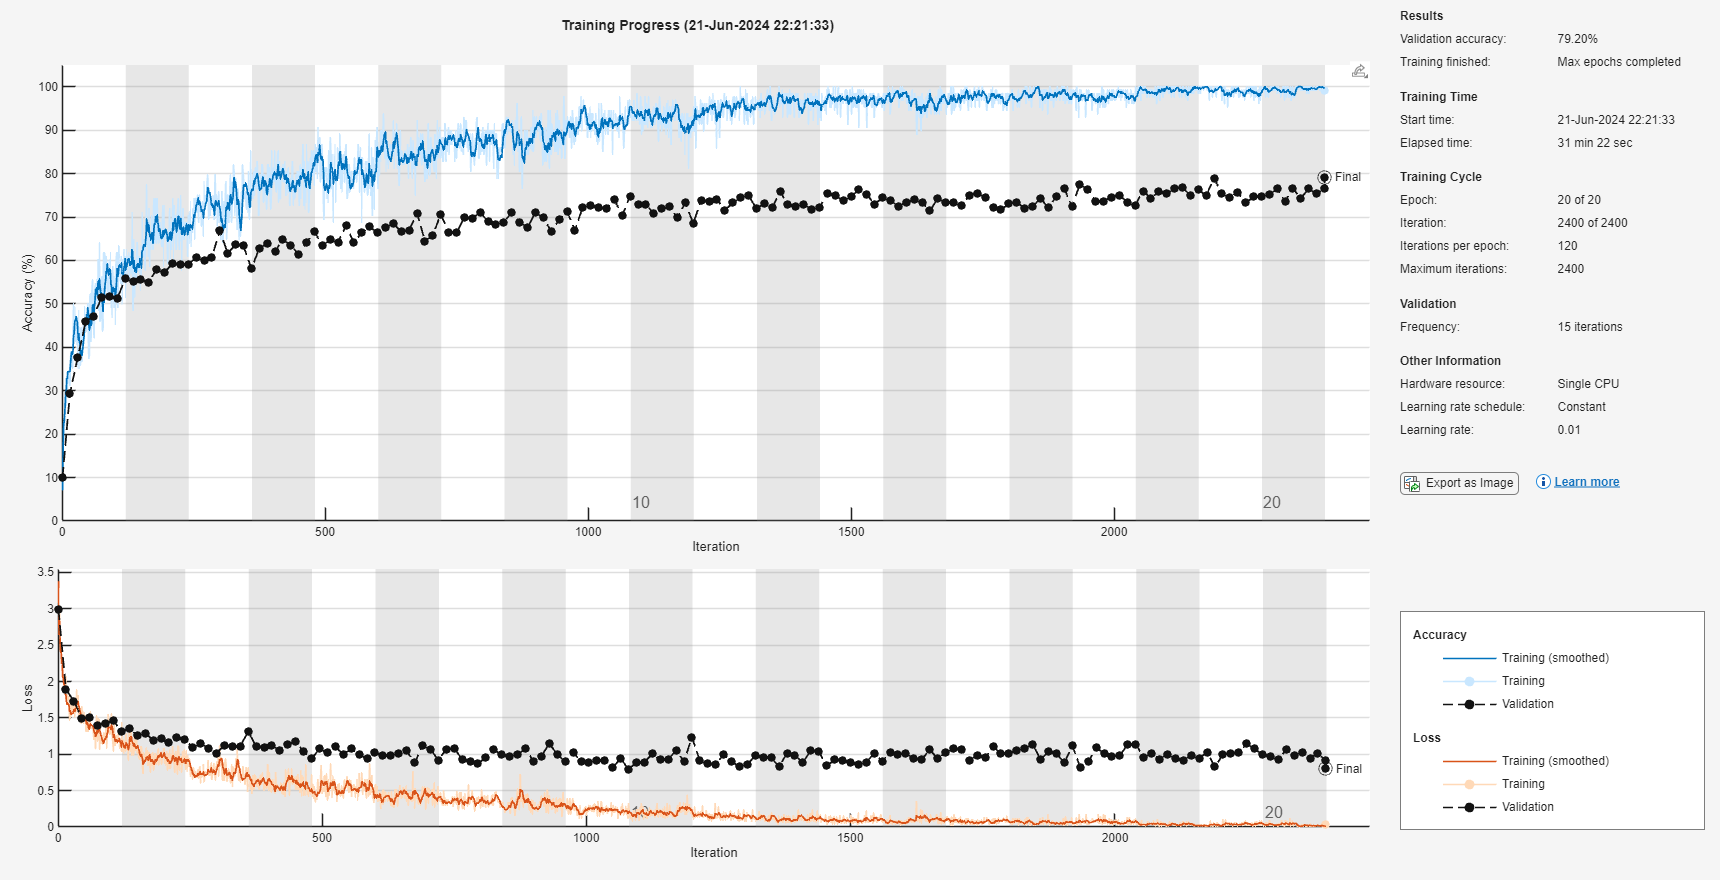

% Train the network
netImproved5 = trainNetwork(trainData, trainLabels, layers, options);

predictedLabels = classify(netImproved5, testData);
accuracy = sum(predictedLabels == testLabels) / numel(testLabels);
fprintf('Test accuracy: %.2f%%\n', accuracy * 100);

Test accuracy: 79.20%


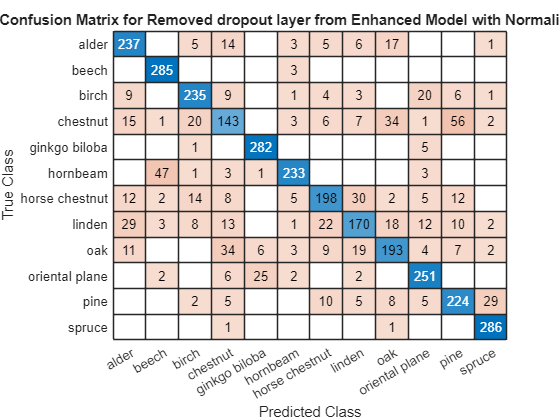

figure;
confusionchart(testLabels, predictedLabels);
title('Confusion Matrix for Removed dropout layer from Enhanced Model with Normalised Data');

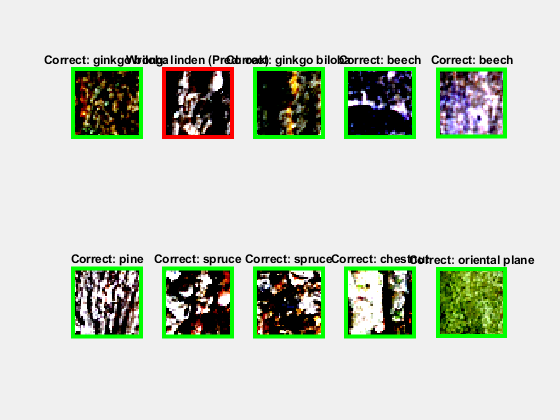

numSamples = 10; 
sampleIndices = randperm(numel(testLabels), numSamples);

figure('Visible', 'on');
for i = 1:numSamples
    index = sampleIndices(i);
    img = testData(:,:,:,index);
    trueLabel = testLabels(index);
    predictedLabel = predictedLabels(index);
    
    subplot(2, numSamples/2, i);
    imshow(img, 'InitialMagnification', 'fit');
    
    if trueLabel == predictedLabel
        borderColor = 'g'; 
        titleText = sprintf('Correct: %s', string(trueLabel));
    else
        borderColor = 'r'; 
        titleText = sprintf('Wrong: %s (Pred: %s)', string(trueLabel), string(predictedLabel));
    end
    
    rectangle('Position', [0.5, 0.5, size(img, 2), size(img, 1)], 'EdgeColor', borderColor, 'LineWidth', 3);
    title(titleText);
end


drawnow;

Remove increased convolutional filters (original filters)

layers = [
    imageInputLayer([40 40 3], 'Normalization', 'none')
    
    convolution2dLayer(3, 32, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(3, 64, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    
    fullyConnectedLayer(256)
    dropoutLayer(0.5) % Add dropout to prevent overfitting
    reluLayer
    
    fullyConnectedLayer(numel(unique(trainLabels)))
    softmaxLayer
    classificationLayer
];

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',20, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{testData, testLabels}, ...
    'ValidationFrequency',15, ...
    'Verbose',false, ...
    'Plots','training-progress');

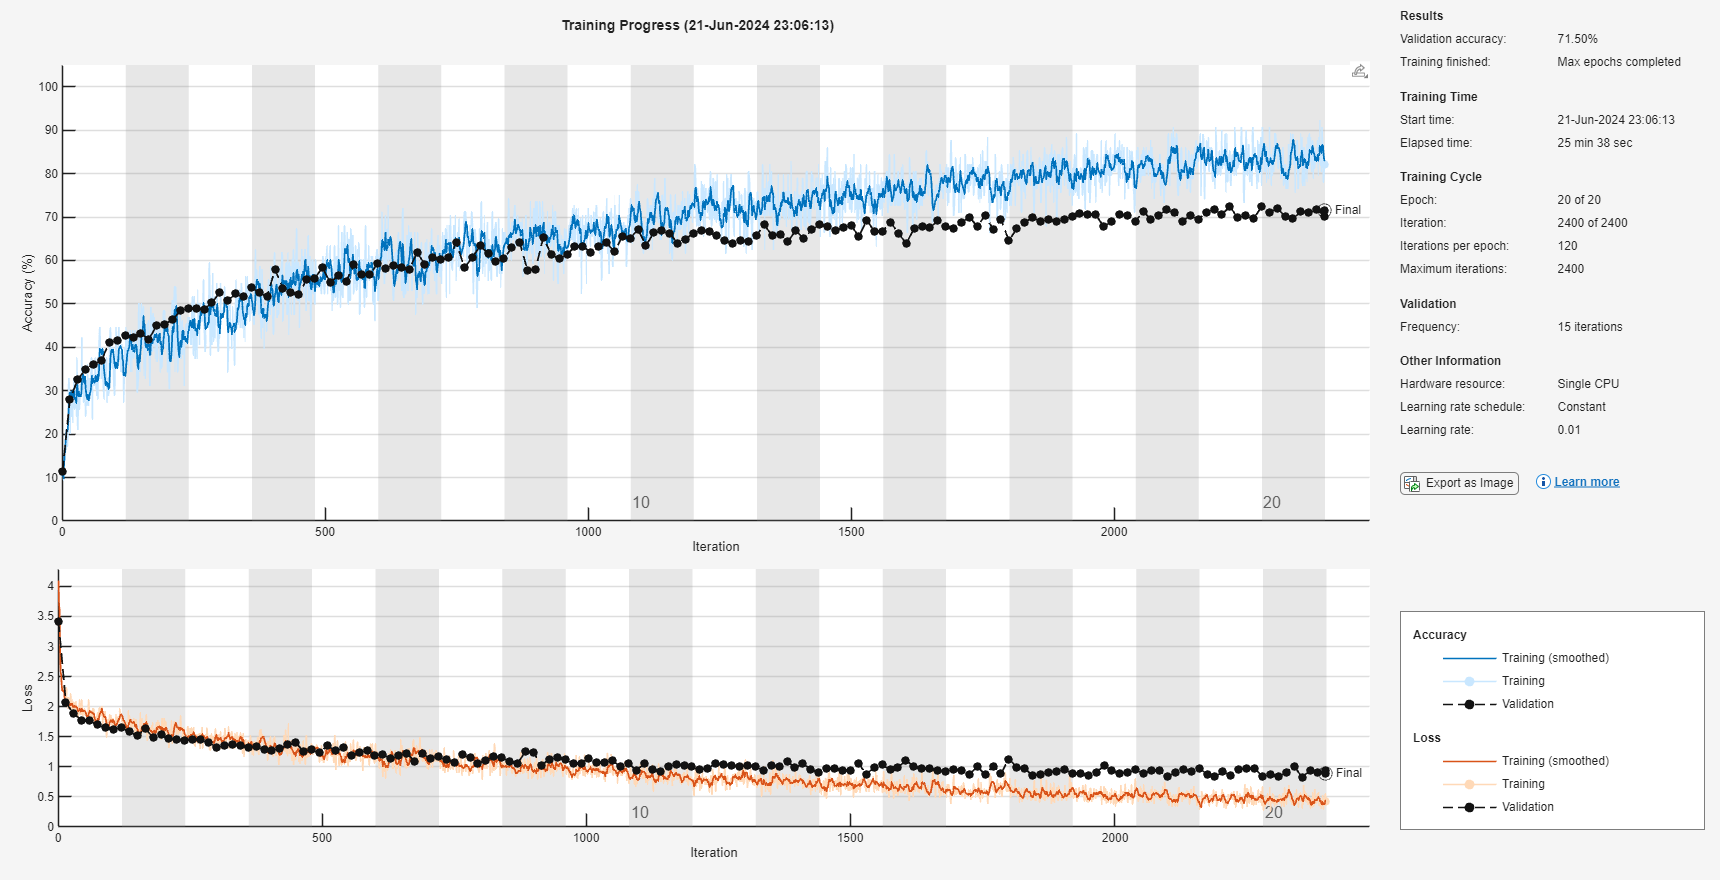

% Train the network
netImproved6 = trainNetwork(trainData, trainLabels, layers, options);

predictedLabels = classify(netImproved6, testData);
accuracy = sum(predictedLabels == testLabels) / numel(testLabels);
fprintf('Test accuracy: %.2f%%\n', accuracy * 100);

Test accuracy: 71.50%


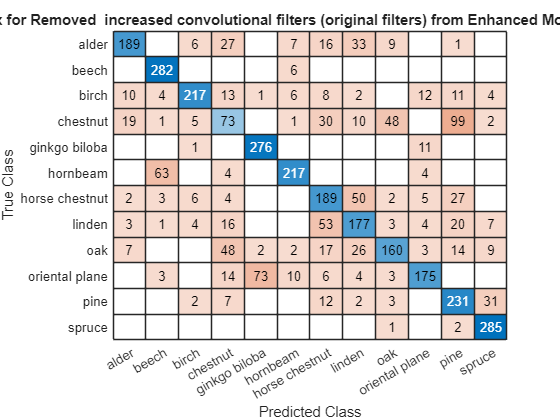

figure;
confusionchart(testLabels, predictedLabels);
title('Confusion Matrix for Removed  increased convolutional filters (original filters) from Enhanced Model with Normalised Data');

numSamples = 10; 
sampleIndices = randperm(numel(testLabels), numSamples);

figure('Visible', 'on');
for i = 1:numSamples
    index = sampleIndices(i);
    img = testData(:,:,:,index);
    trueLabel = testLabels(index);
    predictedLabel = predictedLabels(index);
    
    subplot(2, numSamples/2, i);
    imshow(img, 'InitialMagnification', 'fit');
    
    if trueLabel == predictedLabel
        borderColor = 'g'; 
        titleText = sprintf('Correct: %s', string(trueLabel));
    else
        borderColor = 'r'; 
        titleText = sprintf('Wrong: %s (Pred: %s)', string(trueLabel), string(predictedLabel));
    end
    
    rectangle('Position', [0.5, 0.5, size(img, 2), size(img, 1)], 'EdgeColor', borderColor, 'LineWidth', 3);
    title(titleText);
end

drawnow;